# bwgrowregions() Examples

If you are unable to run this live script, please see `examples.pdf` instead.

## Example 1

Roughly segment a logical image into the parts of the hand according to the distances from the fingertips and wrist. For each pixel, the seed which it is closest to in geodesic distance determines its label.

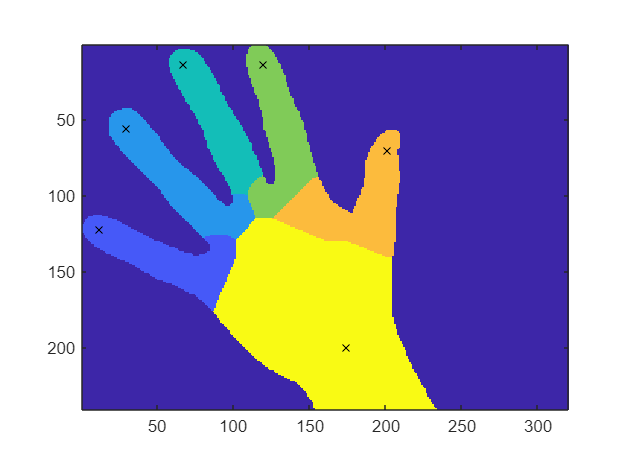

hands = imread( "hands1-mask.png" );
% Label pixels within the hand mask (value = 0).
% Do not label other pixels (value = NaN).
I = nan( size( hands ) );
I(hands) = 0;
% Set seed labels at the tip of each finger and at the wrist.
I(122,12) = 1;
I(56,30) = 2;
I(14,67) = 3;
I(14,120) = 4;
I(70,201) = 5;
I(200,174) = 6;
% Perform region growing. By default bwgrowregions uses a 
% quasi-Euclidean distance metric.
segmentation = bwgrowregions( I );
% Plot the seed locations and results.
segmentation( isnan( segmentation ) ) = 0;
figure
imagesc( segmentation )
hold on
scatter( [12 30 67 120 201 174], [122 56 14 14 70 200], 'kx' )
axis tight equal

## Example 2

Improve previous segmentation with the knowledge that the parts are defined by an underlying skeleton. We therefore first extract and label the skeleton. The labelled skeleton is then used as seeds and grown to segment the entire area of the hand.

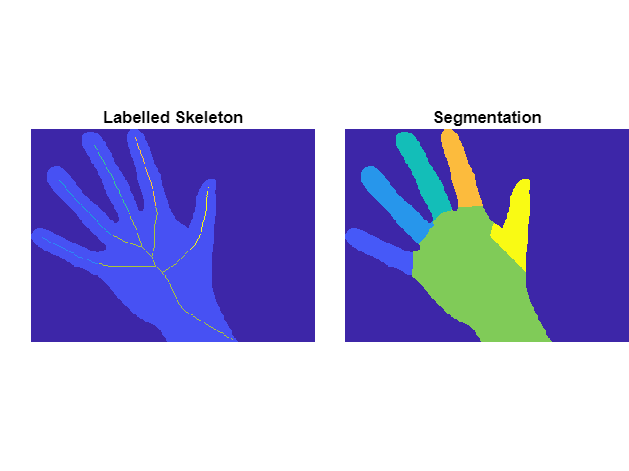

hands = imread( "hands1-mask.png" );
% Extract the skeleton of the hand and give each finger a different label.
skeleton = bwskel( hands );
skeleton([18392,21961,26255,33688,42857]) = false;
skeleton = bwlabel( skeleton );
% Set up the traversable region and use the labelled skeleton as seeds.
I = nan( size( hands ) );
I(hands) = 0;
I = I + skeleton;
% Grow the regions.
segmentation = bwgrowregions( I );
% Plot the seed locations and results.
figure, tiledlayout( 1, 2, 'TileSpacing', 'tight', 'Padding', 'tight' )
nexttile, imagesc( I )
title('Labelled Skeleton'), axis tight equal, clim( [-1 6] )
set( gca, 'XColor', 'none', 'YColor', 'none' )
nexttile, imagesc( segmentation )
title('Segmentation'), axis tight equal, clim( [0 6] )
set( gca, 'XColor', 'none', 'YColor', 'none' )

## Example 3

Segment a volume according to fixed distance intervals along its centerline. The same technique could apply to complex tubular volumes, such as those of the colon, oesophagus, veins, etc.

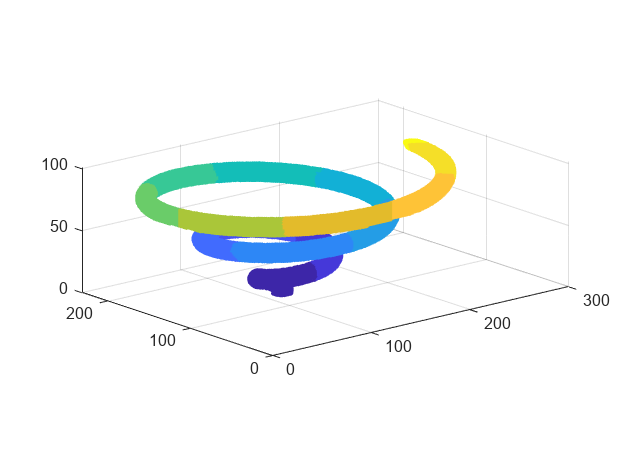

load( 'spiralVol.mat' )
spiralVol = padarray( imresize3( imbinarize( spiralVol ), 0.5 ), [1 1 1] );
% Skeletonize the volume to find its centerline. Then, label the centerline
% into segments according to distance 100 intervals.
centerline = bwskel( spiralVol );
endpoints = find( bwmorph3( centerline, 'endpoints' ) );
distance = bwdistgeodesic( centerline, endpoints(1), 'quasi-euclidean' );
distance = distance( centerline );
segmentDistances = [ 0 : 100 : max( distance ), max( distance ) ];
centerlineLabels = discretize( distance, segmentDistances );
% Use the centerline as seed labels to segmentat the volume.
segmentation = nan( size( spiralVol ) );
segmentation(spiralVol) = 0;
segmentation(centerline) = centerlineLabels;
% Perform the region growing.
segmentation = bwgrowregions( segmentation );
% Plot the resulting segmentation.
figure
axes( 'DataAspectRatio', [1 1 1], 'View', [-40 16], ...
    'XGrid', 'on', 'YGrid', 'on', 'ZGrid', 'on' )
segmentation( isnan( segmentation ) ) = 0;
isosurface( spiralVol, segmentation )